clc
clear
close all

Generate Data

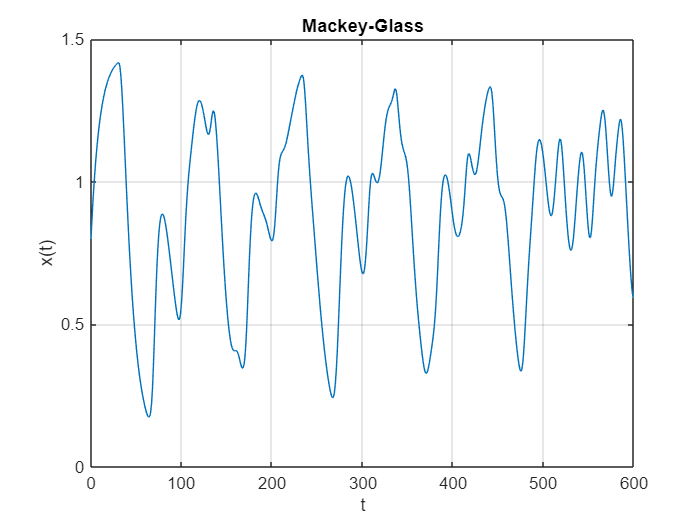

tau = 30; % Delay
dt = 1; % Step
n = 600; % Number of samples
x0 = 0.8; % x(0)

tau_steps = tau/dt;
x = zeros(1, n + tau_steps - 1)';
x(1:tau_steps) = x0;

for t = 0 : n-2
    i = t + tau_steps;
    x_tau = x(i + 1 - tau_steps);
    dx = 0.2 * x_tau / (1 + x_tau^10) - 0.1 * x(i);
    x(i+1) = x(i) + dt * dx;
end

x = x(tau_steps:end);
t = [0:n-1]';

figure
plot(t,x)
title('Mackey-Glass')
xlabel('t')
ylabel('x(t)')
grid on

Preprocess Data

y = x(5:end);
x1 = x(4:end-1);
x2 = x(3:end-2);
x3 = x(2:end-3);
x4 = x(1:end-4);

X = [x1 x2 x3 x4];

% Train Test Split
nTrain = 300;
X_Train = X(1:nTrain,:);
y_Train = y(1:nTrain);
X_Test = X(nTrain:end,:);
y_Test = y(nTrain:end);

% Normalize
[X_Train_norm, settings] = mapminmax(X_Train', 0, 1);
X_Test_norm = mapminmax('apply', X_Test', settings);
X_Train_norm = X_Train_norm';
X_Test_norm = X_Test_norm';

**Train Data**

Model 1

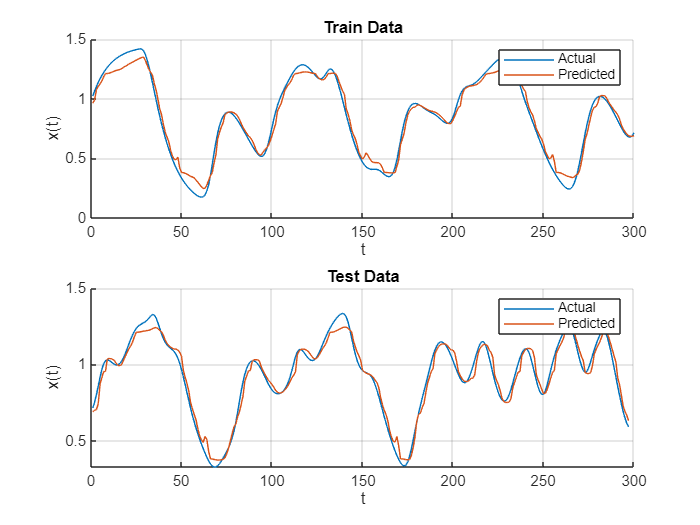

fis1 = CreateFisUsingLookupTable(X_Train_norm, y_Train,[7 7 7 7 7],...
    {'trimf', 'trimf', 'trimf', 'trimf','trimf'});

y_hat1_Train = evalfis(fis1,X_Train_norm);
y_hat1_Test = evalfis(fis1,X_Test_norm);

% Plot Data
figure
subplot(2,1,1)
hold on
plot(y_Train)
plot(y_hat1_Train)
title('Train Data')
ylabel('x(t)')
xlabel('t')
grid on
legend('Actual', 'Predicted')

subplot(2,1,2)
hold on
plot(y_Test)
plot(y_hat1_Test)
title('Test Data')
ylabel('x(t)')
xlabel('t')
grid on
legend('Actual', 'Predicted')

Model 2

fis2 = CreateFisUsingLookupTable(X_Train_norm, y_Train,[15 15 15 15 15],...
    {'trimf', 'trimf', 'trimf', 'trimf','trimf'});

y_hat2_Train = evalfis(fis2,X_Train_norm);
y_hat2_Test = evalfis(fis2,X_Test_norm);

% Plot Data
figure
subplot(2,1,1)
hold on
plot(y_Train)
plot(y_hat2_Train)
title('Train Data')
ylabel('x(t)')
xlabel('t')
grid on
legend('Actual', 'Predicted')

subplot(2,1,2)
hold on
plot(y_Test)
plot(y_hat2_Test)
title('Test Data')
ylabel('x(t)')
xlabel('t')
grid on
legend('Actual', 'Predicted')
